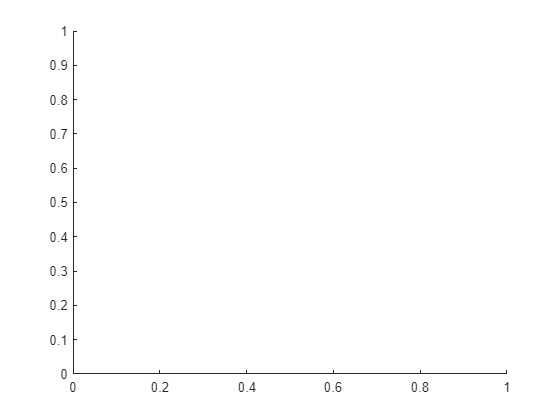

clc
clear
close all
format long

set(0,'DefaultFigureWindowStyle','docked')
hold off

## Test plotting methods using numerical values and built in "streamline" function

Define grid

[x, y] = meshgrid(-5:0.25:5, -5:0.25:5);

% Define uniform flow parameters
uni_vel = 1;    % magnitude of uniform flow, V_inf
uni_thet = deg2rad(0);   % angle of uniform flow (input degrees)

% Define source flow parameters
src_strength = 1;   % strength of the source
src_x = 0;          % x-coordinate of the source
src_y = 0;          % y-coordinate of the source

% Calculate velocity components for uniform flow
u_uni = uni_vel * cos(uni_thet);
v_uni = uni_vel * sin(uni_thet);

% Calculate velocity components for source flow
u_src = src_strength .* (x - src_x) ./ ((x - src_x).^2 + (y - src_y).^2);
v_src = src_strength .* (y - src_y) ./ ((x - src_x).^2 + (y - src_y).^2);

% Total velocity components, based on Laplace'S Equation
u = u_uni + u_src;
v = v_uni + v_src;

% Plot velocity flow field + components
plot(src_x, src_y, Marker=".", MarkerSize=20)
hold on
quiver(x, y, u, v);
xlabel('x');
ylabel('y');
title('Flow Visualization: Uniform and Source Flow');
axis equal
grid

% Stagnation
r_stag = src_strength/(2*pi*uni_vel)

r_stag =    0.159154943091895


thet_Stag = pi

thet_Stag =    3.141592653589793


x_stag = r_stag * cos(thet_Stag)

x_stag =   -0.159154943091895


y_stag = r_stag * sin(thet_Stag)

y_stag =      1.949085916259688e-17


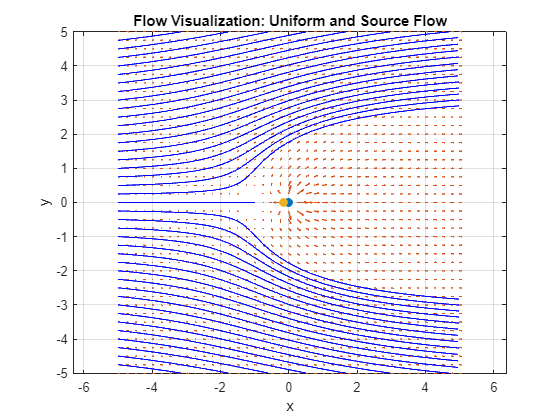


% Plot streamlines
% figure
plot(x_stag, y_stag, Marker=".", MarkerSize=20)
[startX,startY] = meshgrid(-5, -5:0.25:5);
streamline(x,y,u,v,startX,startY)
hold off

## Symbolic Variables

%{
Now use symbolic variables, allowing for indefinite integration of 
velocity components to compute stream and potential functions
%}

clear
syms v_inf thet u v x y 
% v_inf = 1;          % velocity magnitude of uniform flow
% thet = deg2rad(0);  % theta angle of uniform flow w.r.t. horizontal

u = v_inf * cos(thet);
v = v_inf * sin(thet);

y = int(v/u, x)

$$y = \frac{x\,\sin\left(\mathrm{thet}\right)}{\cos\left(\mathrm{thet}\right)}$$

y = subs(y, [v_inf,thet], [1,0])

$$y = 0$$

% y = subs(y, x, -5:1:5)
c = -5:1:5

c =     -5    -4    -3    -2    -1     0     1     2     3     4     5


y = y + c

$$y = \left(\begin{array}{ccccccccccc} -5 & -4 & -3 & -2 & -1 & 0 & 1 & 2 & 3 & 4 & 5 \end{array}\right)$$

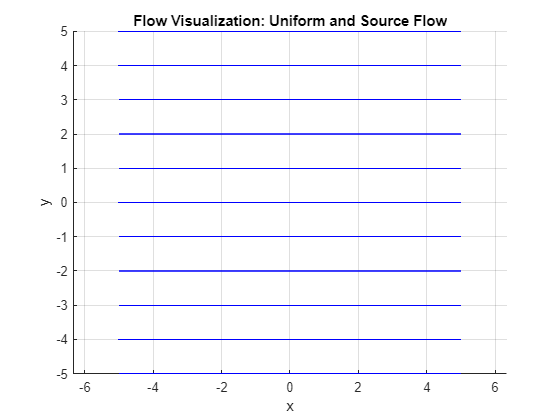


% partial_stream_y = u
% partial_stream_x = -v
% 
% stream_y = int(partial_stream_y, y)
% stream_x = int(partial_stream_x, x)
% stream_uni = stream_x + stream_y
% 
% stream_uni = subs(stream_uni, [v_inf,thet], [1,0])
% xn = subs(x, x, -5:1:5)
% yn = subs(y, y, -5:1:5)
% stream_uni = subs(stream_uni, [x,y], [xn,yn])

figure
% plot(src_x, src_y, Marker=".", MarkerSize=20)
hold on
fplot(y,[-5 5], Color='b')
xlabel('x');
ylabel('y');
title('Flow Visualization: Uniform and Source Flow');
axis equal
grid